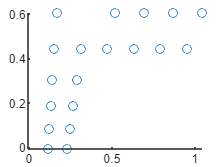

%%% 1.a
Wc=[-2 -2 0 1 2 3 -2 -1 0 1 2 3 -1 -2 -1 -2 -1 -2 -1 -2;0 0 0 0 0 0 1 1 1 1 1 1 2 2 3 3 4 4 5 5;0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
theta=135*pi/180;
f=1.3;
T=[3 3.5 7.5];

CameraModel(Wc,theta,f,T)
scatter(u,v)

%%% 1.b




%%% 3


%%% 4
load("coef2023.mat");
A=coef.A;
B=coef.B/2;
C=coef.C;
D=coef.D/2;
E=coef.E/2;
F=coef.F;

f=.825;
xc=1;yc=1;
syms a b g
S=solve(A+(2*D/f)*a+(F/f^2)*a^2  == C+(2*E/f)*b+(F/f^2)*b^2 ,...
    ((D/f)*b  + (E/f)*a + (F/f^2)*a*b == 0),...
     (A+(2*D/f)*a+(F/f^2)*a^2)*xc^2+(C+(2*E/f)*b+(F/f^2)*b^2)*yc^2+...
     ((D/f)*b  + (E/f)*a + 2*(F/f^2)*a*b)*xc*yc+2*(D/f*g+F/f^2*a*g)*xc+... 
     2*(E/f*g+F/f^2*a*g)*yc +F/f^2*g^2== 0 ,a,b,g );
[a]=double(S.a);
%alpha=.0268; 
alpha=.2842;
[b]=double(S.b);
%beta=-.0039; 
 beta=-1.0928;

%Initially Gamma =1
 r=7.5;
 g=1;
%Equation of plane
 zc=alpha*xc + beta*yc + r; 
%Equation of plane normal
Nc=1/sqrt(alpha^2+beta^2+1)*[alpha beta -1]' 

Nc =     0.1884
   -0.7245
   -0.6630


 %Circle Center
Ac=A+(2*D/f)*alpha+(F/f^2)*alpha^2;
Bc=-(D*f+F*alpha)*g/(f^2);
Cc=-(E*f+F*beta)*g/(f^2);
Dc=F/(f^2)*g^2;

g=1/sqrt((Bc^2+Cc^2-Ac*Dc)/(Ac^2))

g = 2.9171

%Oc=1/Ac*[Bc Cc r*Ac+alpha*Bc+beta*Cc]';
Ac=A+(2*D/f)*alpha+(F/f^2)*alpha^2;
Bc=-(D*f+F*alpha)*g/(f^2);
Cc=-(E*f+F*beta)*g/(f^2);
Dc=F/(f^2)*g^2;
Oc=1/Ac*[Bc Cc g*Ac+alpha*Bc+beta*Cc]'

Oc =    -0.2857
   -1.0386
    3.9709
